# `bedmap2_data` documentation

This function returns Bedmap2 data and corresponding geographic or polar stereographic coordinates. 

This function requires the [Antarctic Mapping Tools](http://www.mathworks.com/matlabcentral/fileexchange/47638) package.

An overview of Bedmap2 functions for AMT can be found in `bedmap_overview.mlx`.

## Syntax

## Description

`Z = bedmap2_data(var)` returns Bedmap2 data of type `var` at full 1 km resolution. `var` options are: 

- `'surface'` surface elevation of the ice (m) relative to gl04c geoid. 

- `'surfacew'` surface elevation of the ice (m) relative to WGS84. 

- `'bed'` bed elevation (m) relative to gl04c geoid. 

- `'bedw'` bed elevation (m) relative to WGS84 ellipsoid. 

- `'thickness'` ice thickness (m) 

- `'beduncertainty'` uncertainty (m)

- `'gl04c'` gl04c geoid (z_wgs84 = z_bedmap2 + gl04c) 

- `'coverage'` binary grid showing distribution of ice thickness data used in the grid of ice thickness 

- `'icemask'` 0 = grounded, 1 = ice shelf, 127 = ocean

- `'rockmask'` 1s indicate rocks

- `'vostok'` 1s indicate Lake Vostok

`Z = bedmap2_data(...,lati,loni)` returns only enough Bedmap2 data to fully encompass a set of points given by geo coordinates `lati,loni`. 

`Z = bedmap2_data(...,lati,loni,extrakm)` as above, but encompasses points `lati,loni` and adds a buffer of specified width `extrakm` in kilometers around all four sides of data points. 

`Z = bedmap2_data(...,xi,yi)` returns only enough Bedmap2 data to fully encompass a set of points given by polar stereographic (-71) coordinates `xi,yi`. 

`Z = bedmap2_data(...,xi,yi,extrakm)` as above, but encompasses points `xi,yi` and adds a buffer of specified width `extrakm` in kilometers around all four sides of data points. 

`Z = bedmap2_data(...,'res',resolution)` specifies a resolution in kilometers. By default, this function returns the full `1` km Bedmap2 data set. 

`[lat,lon] = bedmap2_data('latlon')` returns a `lat,lon` grid of the Bedmap2 data set. 

`[x,y] = bedmap2_data('xy')` returns a polar stereographic (-71) grid of the Bedmap2 data set. 

`[lat,lon,Z] = bedmap2_data(...)` returns geo coordinates and elevation or mask data `Z`. 

`[x,y,Z] = bedmap2_data(...,'xy')` returns polar stereographic coordinates when the `'xy'` tag is included. 

## Example 1: Loading the full Bedmap2 dataset

First, a simple surface: 

sfz = bedmap2_data('surface');

The above returns the full 6667x6667 Bedmap2 surface elevation data set. If you'd like corresponding latitude and longitude values, get them like this: 

[lat,lon] = bedmap2_data('latlon');

The two commands above could just as easily be combined into one, like this: 

[lat,lon,sfz] = bedmap2_data('surface');

Sometimes instead of georeferenced coordinates you want polar stereographic coordinates (with a true latitude of 71°S, of course). Get polar stereographic *x,y* values like this: 

[x,y] = bedmap2_data('xy');

Or equivalently, 

[x,y,sfz] = bedmap2_data('surface','xy');

## Example 2: Subsetting data by region

If you have a specific study region, there is no sense wasting time loading all 4.4 million Bedmap2 data points. And if you perform any fancy mathematics or plotting functions on the full data set using a personal computer, you'll find that the full data set can give your laptop a real workout. Suppose you have the following 25 GPS measurements: 

lat_gps = -71+4*rand(25,1); 
lon_gps = -70+7*rand(25,1);

Load only enough bed elevation data to fully contain your GPS points: 

[lat,lon,bed] = bedmap2_data('bed',lat_gps,lon_gps);

Now we can plot bed topography of only our study area like this: 

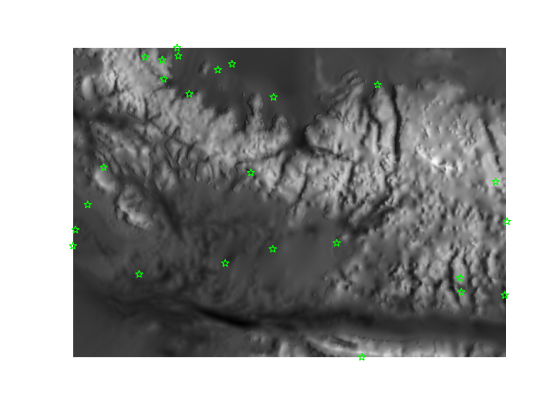

pcolorps(lat,lon,bed) 
colormap(gray(256))
plotps(lat_gps,lon_gps,'gp') % green stars 
shadem(2) % hill shading 
axis tight off % removes white space and axes

That map doesn't give the near-edge data points much context. Let's add a 100 km buffer around the GPS data points like this: 

[lat,lon,bed] = bedmap2_data('bed',lat_gps,lon_gps,100);

and plot: 

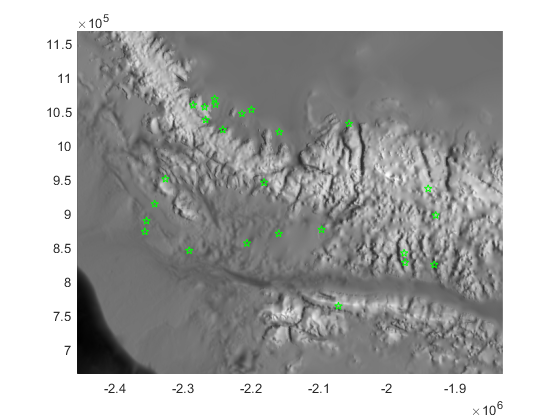

figure
pcolorps(lat,lon,bed) 
colormap(gray(256))
plotps(lat_gps,lon_gps,'gp')
shadem(2)
axis tight

## Example 3: Specifying resolution

This function will return downsampled data. Data are downsampled simply by loading only every nth point of the full Bedmap2 data set. To downsample in a more proper fashion, you may wish to perform a low-pass filter on the full data set, then sample every nth data point. 

Here we get a whole continent's worth of Bedmap2 data downsampled to 5 km:

[lat,lon,bed] = bedmap2_data('bed','res',5);

Or using the data from Example 2, get 2 km resolution data within a region bounding some data, with a 75 km buffer around the data: 

[x,y,bed] = bedmap2_data('bed',lat_gps,lon_gps,75,'res',2,'xy');

## References

If this function is useful for you, please cite the following: 

Fretwell, P., et al. "Bedmap2: improved ice bed, surface and thickness datasets for Antarctica." The Cryosphere 7.1 (2013). [http://dx.doi.org/10.5194/tc-7-375-2013](http://dx.doi.org/10.5194/tc-7-375-2013) 

Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

The `bedmap2_data` function and supporting documentation were written by  [Chad A. Greene](http://www.chadagreene.com) of the University of Texas at Austin's Institute for Geophysics (UTIG). Feel free to email Chad at any time to talk about Matlab, Bedmap2, or anything else. Handwritten correspondence is nice, too. 